% %% Uncertainty Estimation for Pressure Time Series using Block Bootstrap
% % Author: Adapted from the methodology in "Uncertainty evaluation in time-dependent measurements"
% % This code performs block bootstrap resampling, model refitting, and computes standard deviations.
% 
% clear; clc; close all;
% 
% % Load data
% load('E2038.mat');  % Assuming 'p' contains multiple pressure data channels
% 
% % Remove DC offset (baseline correction using first 100 samples)
% data = p(:,3) - mean(p(1:100,3)); % Use desired channel (modify index if needed)
% Fs = fs;  % Sampling frequency (Hz)
% t = (0:length(data)-1)'/Fs;  % Time vector
% N =length(data);
% y = data;
% 
% %% Block Bootstrap Parameters
% R = 200;            % Number of bootstrap samples (increased for better CI estimation)
% l = round(N^(1/3)); % Block length (cube root of N)
% n_blocks = ceil(N/l); % Number of blocks per sample
% 
% %% Block Bootstrap Resampling
% rng(0); % For reproducibility
% bootstrap_samples = zeros(N, R);
% 
% for r = 1:R
%     % Generate random block start indices
%     start_idx = randi(N - l + 1, n_blocks, 1);
% 
%     % Build bootstrap sample by concatenating blocks
%     sample = [];
%     for b = 1:n_blocks
%         block = y(start_idx(b):start_idx(b)+l-1);
%         sample = [sample; block];
%     end
% 
%     % Trim to original length
%     bootstrap_samples(:, r) = sample(1:N);
% end
% 
% %% Fit AR(1) Model to Each Bootstrap Sample
% phi_hat = zeros(R, 1);
% sigma_hat = zeros(R, 1);
% 
% for r = 1:R
%     sample_r = bootstrap_samples(:, r);
% 
%     % Fit AR(1) model using Yule-Walker equations
%     ar_coeffs = aryule(sample_r, 1);
%     phi_hat(r) = -ar_coeffs(2); % AR(1) coefficient
%     residuals = filter(ar_coeffs, 1, sample_r);
%     sigma_hat(r) = std(residuals); % Residual standard deviation
% end
% 
% %% Simulate Paths Using Fitted Models
% simulated_paths = zeros(N, R);
% 
% for r = 1:R
%     % Initialize simulation with same initial value
%     y_sim = zeros(N, 1);
%     y_sim(1) = y(1);
% 
%     % Simulate AR(1) process
%     for t = 2:N
%         y_sim(t) = phi_hat(r)*y_sim(t-1) + randn*sigma_hat(r);
%     end
%     simulated_paths(:, r) = y_sim;
% end
% 
% %% Calculate Statistics
% % Compute percentiles for 95% confidence interval
% alpha = 0.05;
% lower_bound = prctile(simulated_paths, 100*(alpha/2), 2);
% upper_bound = prctile(simulated_paths, 100*(1-alpha/2), 2);
% 
% % Compute mean and standard deviation
% mean_estimate = mean(simulated_paths, 2);
% stdev_estimates = std(simulated_paths, 0, 2);
% 
% %% Visualization
% figure;
% subplot(2,1,1);
% hold on;
% % Plot confidence interval shading
% fill([t; flipud(t)], [lower_bound; flipud(upper_bound)], [0.9 0.9 0.9],...
%     'EdgeColor', 'none', 'FaceAlpha', 0.5);
% % Plot original data
% plot(t, y, 'b', 'LineWidth', 1.5);
% title('Pressure Time Series with 95% Confidence Interval');
% xlabel('Time (s)');
% ylabel('Pressure');
% legend('95% CI', 'Original Data', 'Location', 'best');
% grid on;
% 
% subplot(2,1,2);
% plot(t, stdev_estimates, 'r', 'LineWidth', 1.5);
% title('Estimated Standard Deviation');
% xlabel('Time (s)');
% ylabel('Standard Deviation');
% grid on;
% 
% % Adjust plot spacing
% set(gcf, 'Position', [100 100 800 600]);


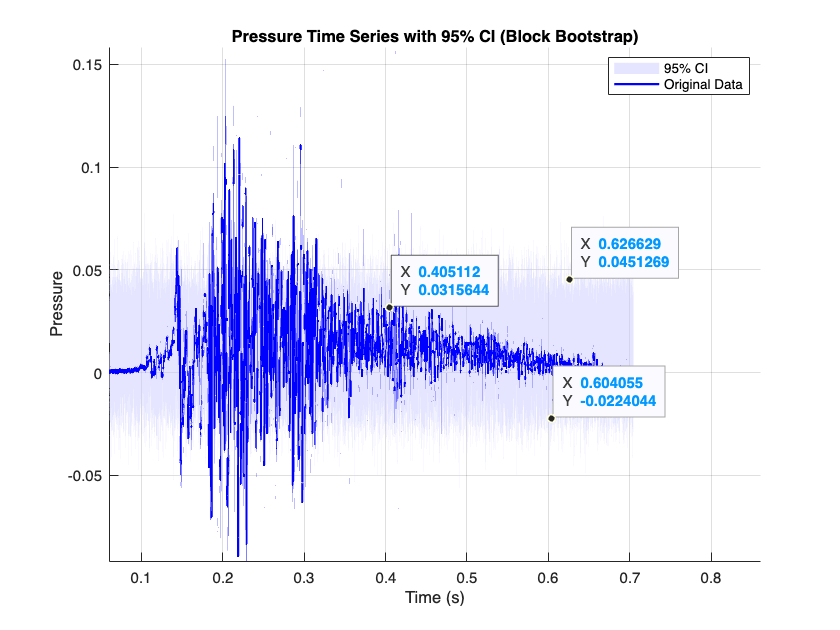

%% Non-overlapping Block Bootstrap for Pressure Time Series Uncertainty
clear; clc; close all;

% Load data
load('E2038.mat');
data = p(:,3) - mean(p(1:100,3)); % DC offset removal
Fs = fs;  % Sampling frequency
N = length(data);
t = (0:N-1)'/Fs;

%% Block Bootstrap Parameters
block_length = 20;  % Set based on dominant timescale (e.g., 20 samples)
R = 200;            % Number of bootstrap samples
n_blocks = floor(N/block_length);

%% Create Non-overlapping Blocks
blocks = reshape(data(1:n_blocks*block_length), block_length, n_blocks)';

%% Block Bootstrap Resampling
bootstrap_samples = zeros(n_blocks*block_length, R);

for r = 1:R
    % Resample blocks with replacement
    resampled_idx = randi(n_blocks, n_blocks, 1);
    bootstrap_sample = blocks(resampled_idx, :);
    
    % Flatten and trim to original length
    bootstrap_samples(:, r) = reshape(bootstrap_sample', [], 1);
end

%% Calculate Statistics
% Compute percentiles for 95% CI
alpha = 0.05;
lower_bound = prctile(bootstrap_samples, 100*(alpha/2), 2);
upper_bound = prctile(bootstrap_samples, 100*(1-alpha/2), 2);

% Compute statistics
mean_estimate = mean(bootstrap_samples, 2);
stdev_estimates = std(bootstrap_samples, 0, 2);

%% Visualization
figure;
hold on;

% Shaded confidence interval
fill([t(1:n_blocks*block_length); flipud(t(1:n_blocks*block_length))],...
    [lower_bound; flipud(upper_bound)], [0.8 0.8 1],...
    'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Plot original data
plot(t, data, 'b', 'LineWidth', 1.5);
title('Pressure Time Series with 95% CI (Block Bootstrap)');
xlabel('Time (s)');
ylabel('Pressure');
legend('95% CI', 'Original Data', 'Location', 'best');
grid on;

x5CIPatch = findobj(gcf, "DisplayName", "95% CI")
datatip(x5CIPatch,0.6041,-0.0224);
datatip(x5CIPatch,0.6266,0.04513);


%% Key Advantages
% 1. Preserves local temporal structure within blocks
% 2. Simpler implementation than moving block bootstrap
% 3. More stable results for periodic/seasonal patterns
% 4. Directly estimates empirical distribution of measurements

% Optional: Compare with moving block bootstrap results
% (Use code from previous implementation for comparison)